Interface02NEulerNRK2

Teste das funções NEuler e NRK2 com exemplo da sebenta de AM2


$$y'=y+e^{3t}, \quad t \in [1,1.5], \quad y(1)=2, \quad \text{com } n=2$$


Arménio Correia | armenioc@isec.pt

aula04T | 05/03/2024

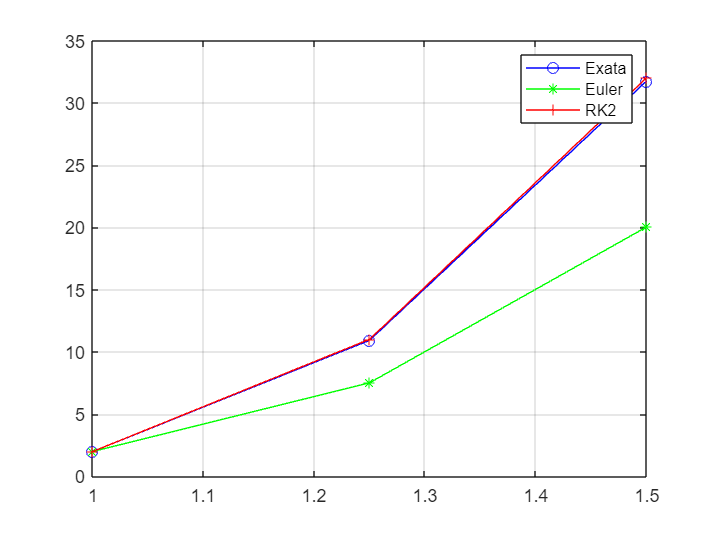

clear

% Dados
% help function_handle
strF = "y+exp(3*t)";
f = @(t,y) eval(vectorize(strF));
a = 1;
b = 1.5;
n = 2;
y0 = 2;

% solução exata do problema
syms y(t);
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
% % gráfico da solução exata no intervalo [a,b]
% fplot(sExata,[a,b]);
% solução exata do problema (expressão numérica)
g = @(t) eval(vectorize(char(sExata)));

% resultados e tabela de resultados
[t,yEuler] = NEuler(f,a,b,n,y0);
[~,yRK2] = NRK2(f,a,b,n,y0);

yExata = g(t);
erroEuler = abs(yExata-yEuler);
erroRK2 = abs(yExata-yRK2);

A = [t.',yExata.',yEuler.',yRK2.',erroEuler.',erroRK2.'];
tabelaResultados = array2table(A,"VariableNames", ...
                   ["t","Exata","Euler","RK2","erroEuler","erroRK2"]);

% representação gráfica
plot(t,yExata,"-bo");
hold on;
plot(t,yEuler,"-g*");
plot(t,yRK2,"-r+");
hold off;
grid on;
legend('Exata','Euler',"RK2");